# *Practica 8: Filtro de una señal*

***Diego Castro Elvira #3***

*8 de diciembre del 2023*

*Procesamiento de señales*

`Cargar archivo de audio`

[audio,samplingRate] = audioread('C:\Users\Khoss\Documents\MATLAB\Programas MATHLAB\ProcesamientoSenales\Practica_8\ejemplo.wav');

`Duración del audio`

duration = length(audio)/samplingRate;

`señales de los canales izquierdo y derecho`

leftChannel = audio(:, 1);
rightChannel = audio(:, 2);

`señal promedio de ambos canales`

averageSignal = 0.5 * (leftChannel + rightChannel).';
sound(averageSignal, samplingRate)

`Vector de tiempo y grafica`

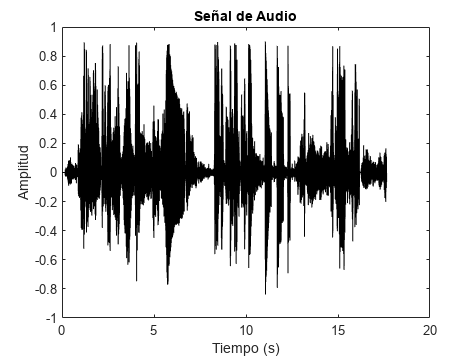

timeVector = linspace(0, duration, length(averageSignal));
figure();
plot(timeVector, averageSignal,'k');
title('Señal de Audio');
xlabel('Tiempo (s)');
ylabel('Amplitud');

`Frecuencia de corte y ancho de banda de transición  en Hz`

cutoffFrequency  = 1000; 
transitionBandwidth = 7000;
normalizedCutoff = cutoffFrequency / (samplingRate/2);
normalizedBandwidth = transitionBandwidth / (samplingRate/2);
filterOrder = 5.5/normalizedBandwidth;

`respuesta al impulso del filtro`

index = 0:filterOrder;
idealResponse = (sin(2 * pi * normalizedCutoff * (index - (filterOrder/2)))) / (index - (filterOrder/2));
blackmanWindow = 0.42 - 0.5 * cos(2*pi*index/filterOrder) + 0.08 * cos(4*pi*index/filterOrder);
filteredResponse = idealResponse.*blackmanWindow;

`Grafica de la respuesta al impulso con ventana Blackman`

figure;
subplot(3,1,1);
stem(index, blackmanWindow, 'g');
title('Ventana Blackman para la Respuesta al Impulso');
xlabel('Muestras');
ylabel('Amplitud');

subplot(3,1,2);
stem(index, filteredResponse,'r');
title('Respuesta al Impulso Filtrada con Ventana Blackman');
xlabel('Muestras');
ylabel('Amplitud');

`Filtrar la señal de audio`

pause(17);
filteredAudio = filter(filteredResponse, 1, averageSignal);

`Grafica de la señal de audio filtrada`

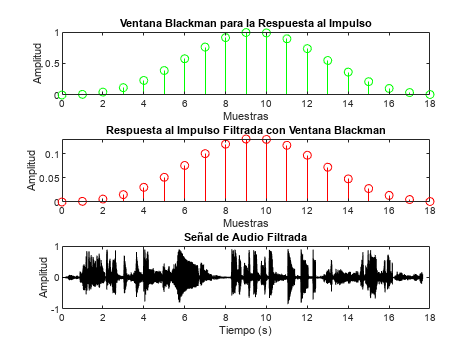

subplot(3,1,3);
plot(timeVector, filteredAudio, 'k');
title('Señal de Audio Filtrada');
xlabel('Tiempo (s)');
ylabel('Amplitud');


sound(filteredAudio,samplingRate)